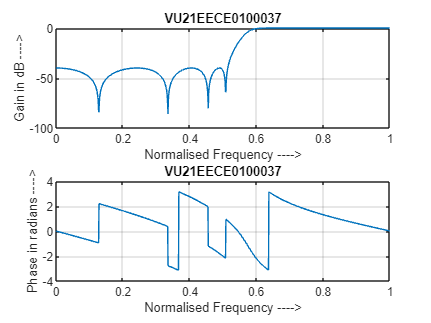

clc;
clear all;
rp = input('Enter the passband ripple 0.25 = ');
rs = input('Enter the stopband ripple 40 = ');
wp = input('Enter the passband frequency 1400 = ');
ws = input('Enter the stopband frequency 1800= ');
fs = input('Enter the sampling frequency 7000 = ');
w1 = 2*wp/fs;
w2 = 2*ws/fs;
[n,wn] = cheb2ord(w1,w2,rp,rs);
[b,a] = cheby2(n,rs,wn,'high');
w = 0:0.01/pi:pi;
[h,om] = freqz(b,a,w);
m = 20*log10(abs(h));
an = angle(h);
subplot(2,1,1);
plot(om/pi,m);
title('Magnitude Response');
ylabel('Gain in dB ---->');
xlabel('Normalised Frequency ---->');
title('VU21EECE0100037');
grid on;
subplot(2,1,2);
plot(om/pi,an);
title('Phase Response');
xlabel('Normalised Frequency ---->');
ylabel('Phase in radians ---->');
title('VU21EECE0100037');
grid on;